UGHHH!!!! 

% Initialize an empty struct to hold parameters
params = struct();

params.filtering = 'fir';
params.filter_order = 4;
params.approx_method = 'chebychevI'; 
params.filter_type = 'bp';
params.cutoff_frequencies = [1000 4000]

params = struct with fields:
             filtering: 'fir'
          filter_order: 4
         approx_method: 'chebychevI'
           filter_type: 'bp'
    cutoff_frequencies: [1000 4000]


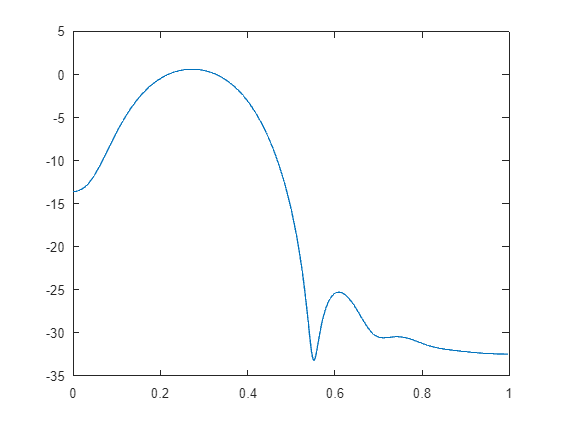

params.target_fs = 20000;
effective_length_percentage = 0.5;

[b,a] = design_filter(params, effective_length_percentage);

function [b, a] = design_filter(params, effective_length_percentage)
  
% Normalize cutoff frequencies for digital filter design
cutoff_frequencies = params.cutoff_frequencies;
filter_type = params.filter_type;
filter_order = params.filter_order;
filtering = params.filtering;
approx_method = params.approx_method;
fs = params.target_fs;

Wn = cutoff_frequencies / (fs / 2); % Normalize by Nyquist frequency
    
    switch  filter_type
        case 'lp'
            filter_response = 'low';
        case 'hp'
            filter_response = 'high';
        case 'bp'
            filter_response = 'bandpass';
        case 'bs'
             filter_response = 'stop';
        otherwise
            error('Invalid response type')
    end

    % Design the filter
    switch approx_method
        case 'butterworth'
           [b, a] = butter(filter_order, Wn, filter_response);
        case 'chebychevI'
            [b, a] = cheby1(filter_order, 0.5, Wn, filter_response); % 0.5 dB ripple
        case 'chebychevII'
            [b, a] = cheby2(filter_order, 20, Wn, filter_response); % 20 dB attenuation
        case 'cauer'
            [b, a] = ellip(filter_order, 0.5, 20, Wn, filter_response); % Elliptic filter
        otherwise
            error('Invalid approximation method for IIR.');
    end

    if strcmp(filtering,'fir')
        % Getting the impulse response
        [h,t] = impz(b,a);
        effective_length = find(abs(h) > 0.1 * max(abs(h)), 1, 'last'); % Effective length
        shortened_length = round(effective_length * effective_length_percentage);

        h_short = h(1:shortened_length); % shorten the impulse response

        a = 1;
        b = h_short;

        % Calculate frequency response of the shortened filter
        [H, w] = freqz(h_short, 1); % '1' as the denominator for FIR structure

         % Plot the frequency response
        plot(w/pi, 20*log10(abs(H)));

    end

    
end